% 实验7 二项分布与正态分布的关系

p = 0.5

p = 0.5000

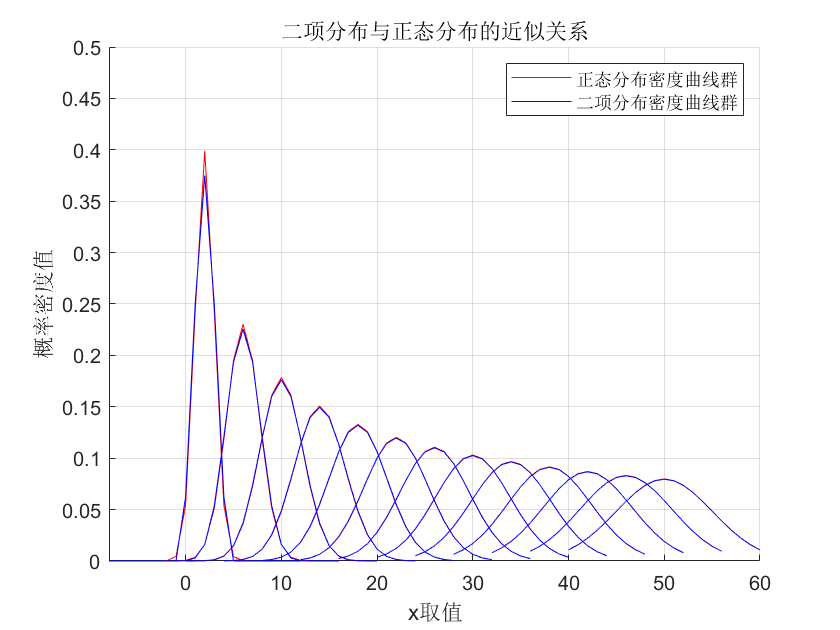


norm_ys = zeros(13, 21);
bin_ys = zeros(13, 21);
xs = zeros(13, 21);

cnt = 1;
% 取n = 4到n = 100时的分布
for n = 4:8:100
    mu = n * p;      
    x_range = round(mu);    % mu可能不是整数
    sig = sqrt(n * p * (1 - p));
    x = (x_range - 10):1:(x_range + 10);
    norm_ys(cnt, :) = normpdf(x, mu, sig);
    bin_ys(cnt, :) = binopdf(x, n, p);
    xs(cnt, :) = x;
    cnt = cnt + 1;
end

hold on; axis on; grid on;
for n = 1:13
    plot(xs(n, :), norm_ys(n, :), "r");
    plot(xs(n, :), bin_ys(n, :), "b");
end
legend(["正态分布密度曲线群", "二项分布密度曲线群"]);
xlim([xs(1, 1), xs(13, 21)]);
ylim([0, 0.5]);
xlabel("x取值");
ylabel("概率密度值");
title("二项分布与正态分布的近似关系");